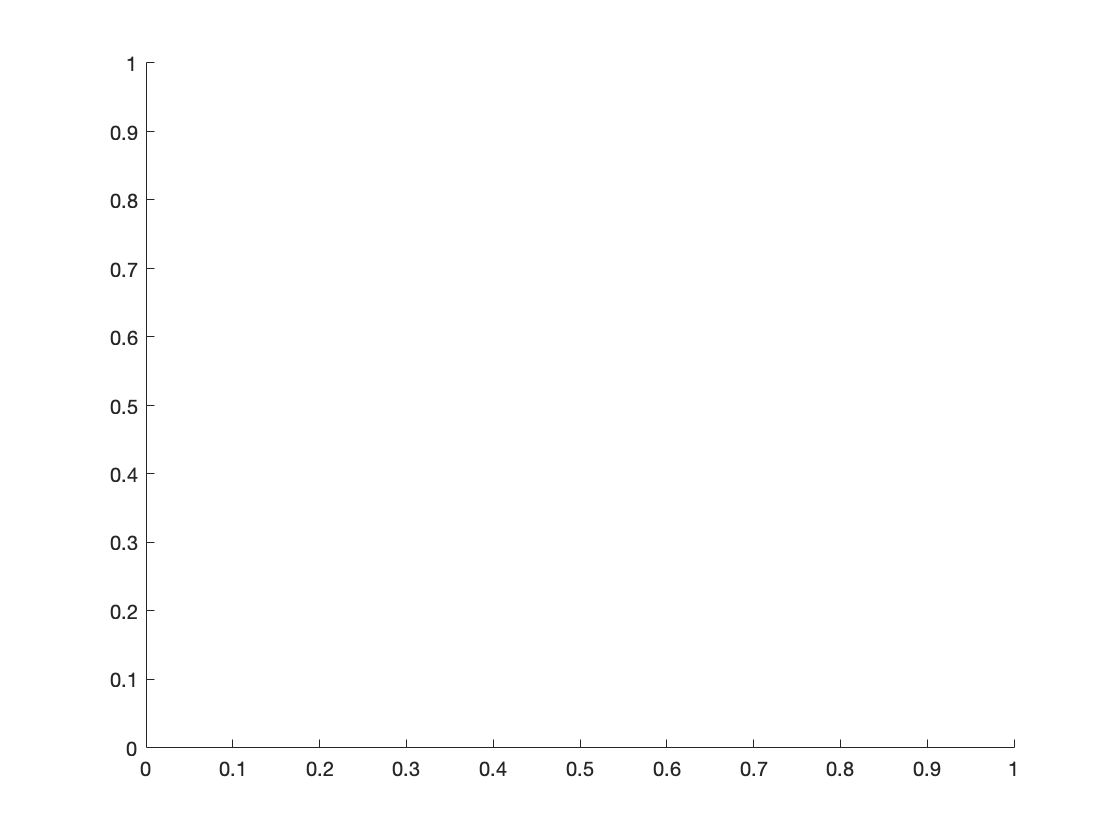

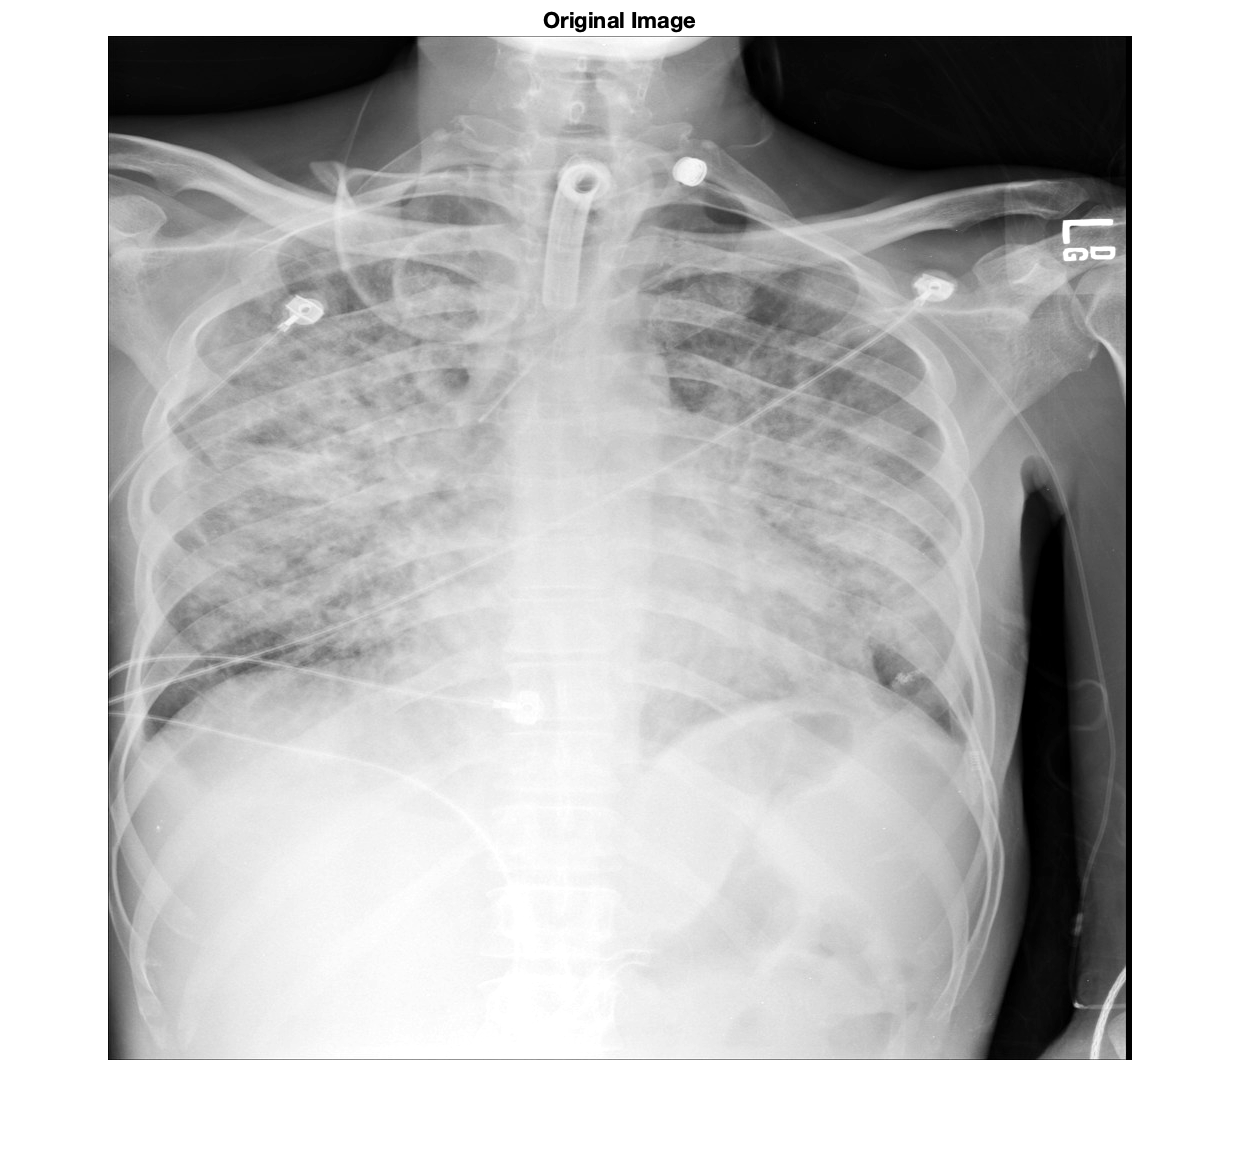


clc; clear; close all;
%%Create Data Stores
d1 = "Final Project/stage_2_train_images/Positive/";
files = dir(fullfile(d1));
files([files.isdir]) = [];
n_files = length(files);

for i = 2:2
    filename = fullfile(d1, files(i).name);
    hold on
    % Read file and gray scale
    figure;
    img = dicomread(filename);
    img = im2gray(img);
    img = imadjust(img);
    imshow(img)
    title("Original Image");
end

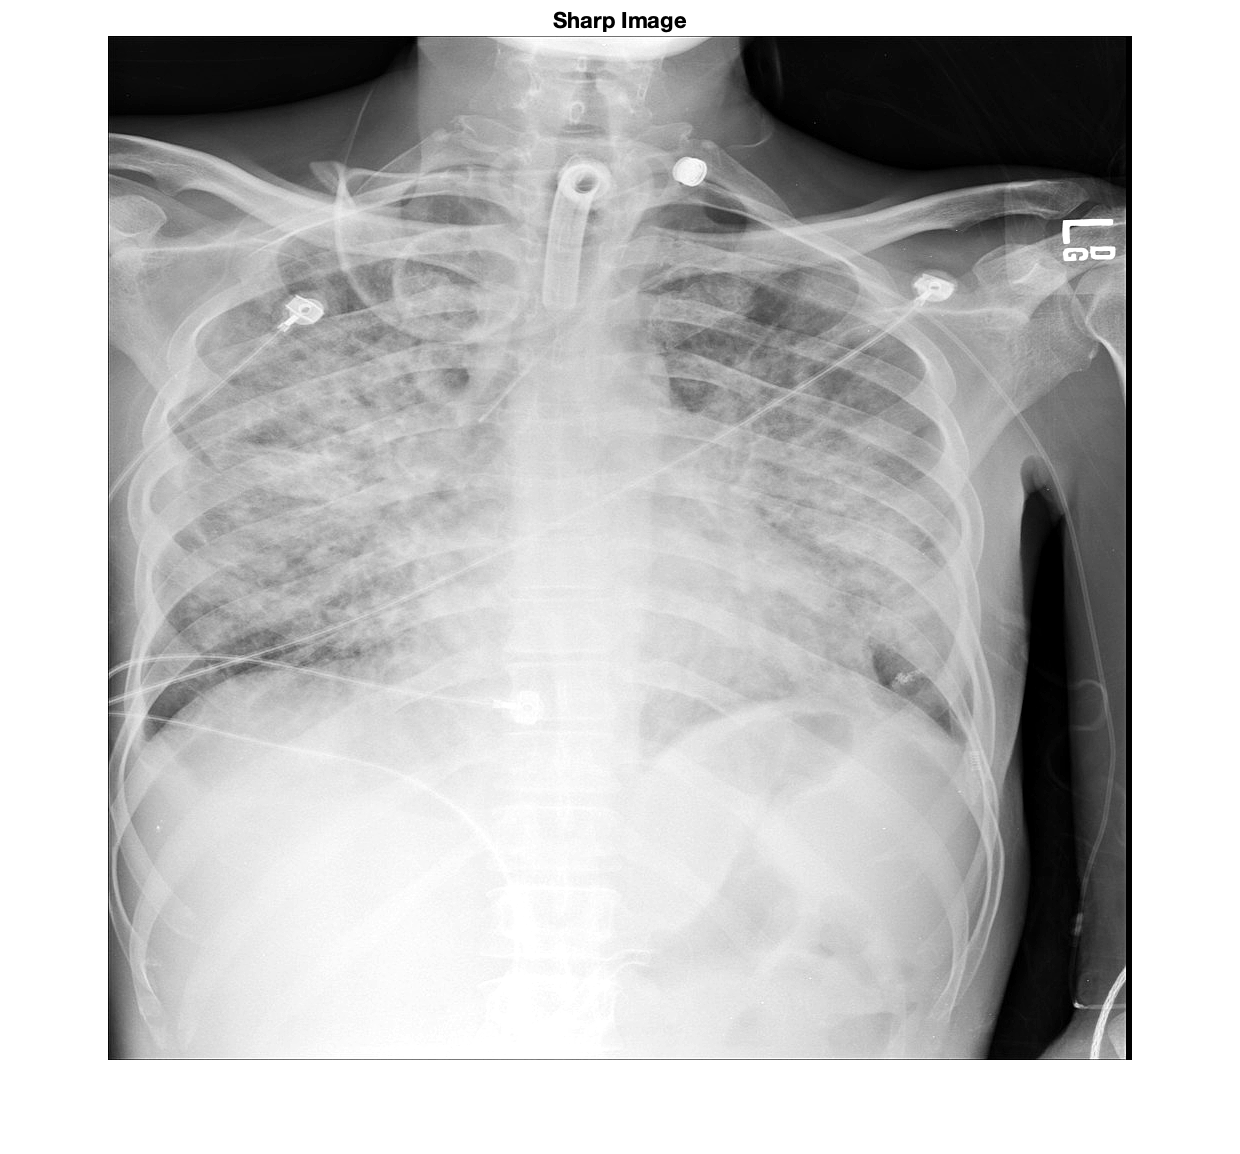

    % Sharpening
    img_sharp = imsharpen(img);
    imshow(img_sharp)
    title("Sharp Image");

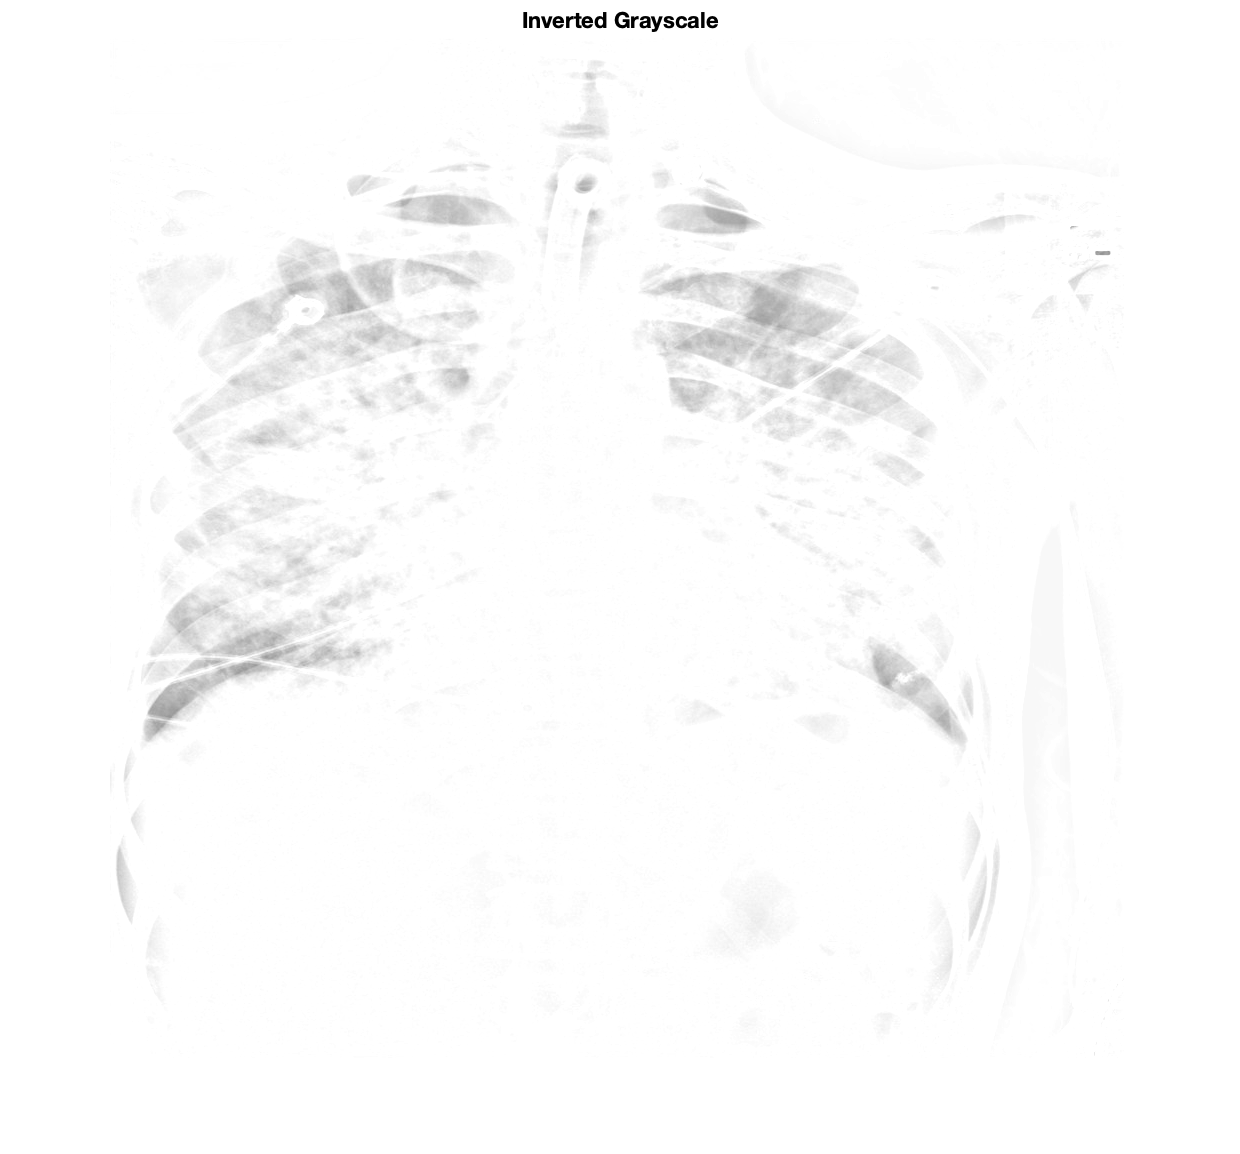

    
    testimg = 255 - img;
    testimg_clear = imclearborder(testimg);
    testimg_clear_inv = 255-testimg_clear;
    imshow(testimg_clear_inv)
    title("Inverted Grayscale");

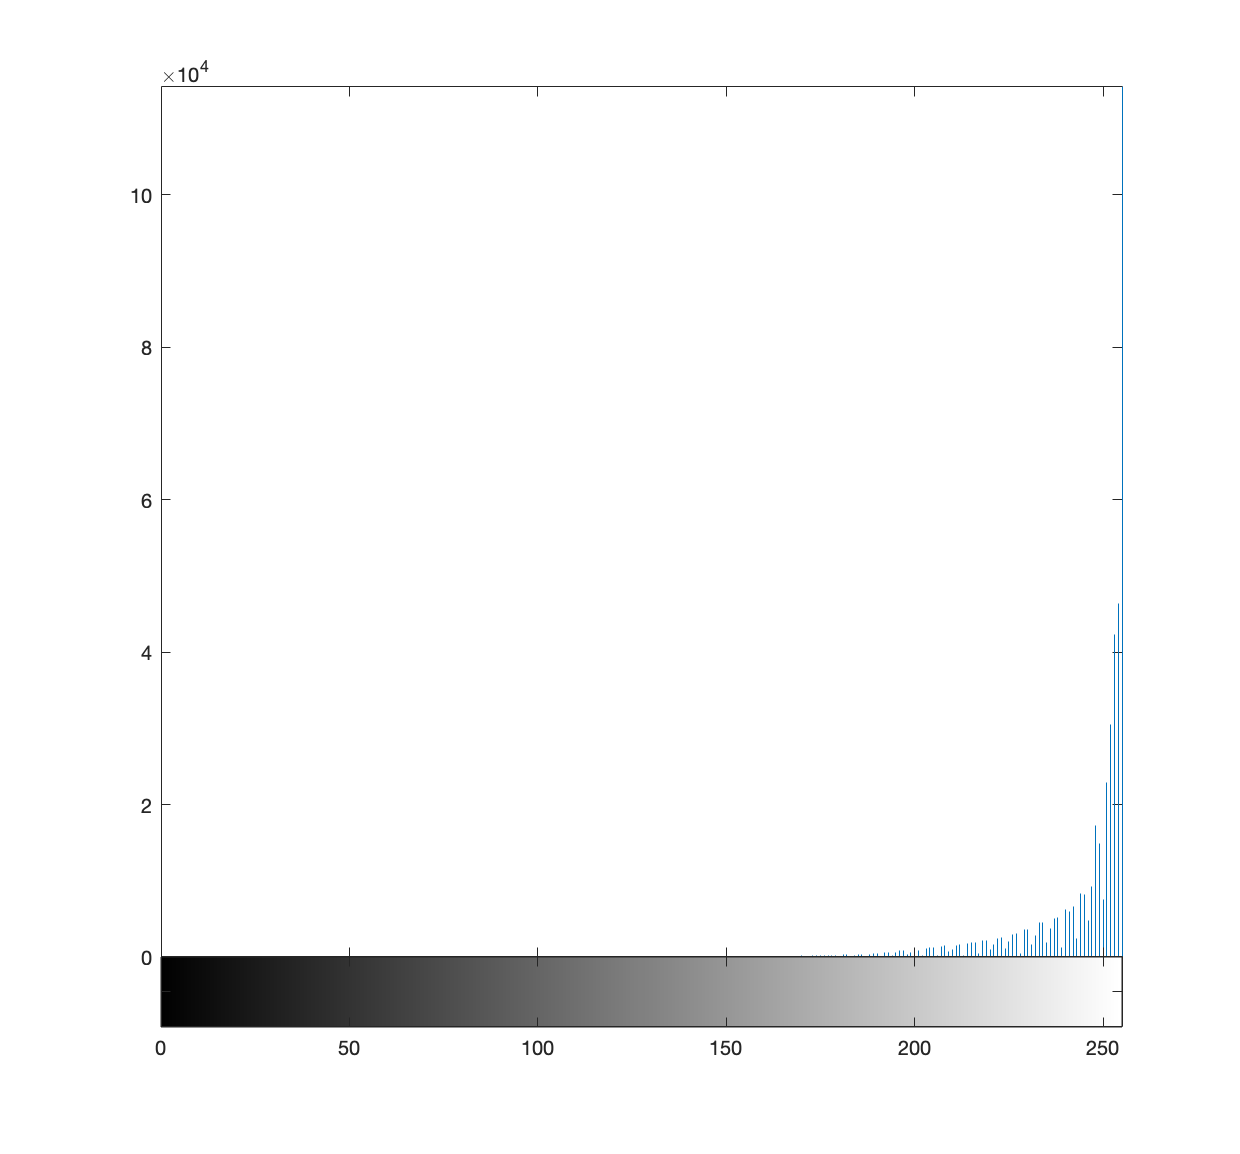

    imhist(testimg_clear_inv)